# Crashcourse in Matlab - Part VII: Odds N Ends

These are just some of the things that will be useful that didn't fit in anywhere else.

## Structures

As codes grow more complex functions often need a large number of inputs and may give a large number of outputs. If you would have to pass all these individually your code would quickly become unreadable. [Structures](https://www.mathworks.com/help/matlab/structures.html) are ways that allow you to collect large amounts of information and then pass them as one piece. For example, we can collect all the information about our grid in a structure as follows.

Grid.xmin = 0;
Grid.xmax = 10;
Grid.ymin = 0;
Grid.ymax = 1;
Grid.Nx = 15;
Grid.Ny = 5;
Grid.coord = 'cartesian';

Grid.Nx

ans = 15

Note that you can have different types of fields (numbers, vectors, matrices, and strings) in the same structure.

## Logical indexing

In many cases it is usefult to access parts of arrays based on [logical conditions](https://blogs.mathworks.com/loren/2013/02/20/logical-indexing-multiple-conditions/). This could be done with for-loops and if-statements, but matlab has a clean vectorized way of acomplishing this. 

Suppose you have geothermal profile and you want to find all the elements of an array above a certain temperature to determine where the crust is partially molten.

clf
H = 40; % crustal thinkness in km
Tsurf = 150; % surface temperature in Kelvin
Tbase = 245; % basal temperature in Kelvin
Tmelt = 200;    % selected temperature in Kelvin
depth = linspace(0,H,1e2);
T = Tsurf + (Tbase-Tsurf)*depth/H;
clf
h = figure

h =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 278 560 420]
       Units: 'pixels'

  Show all properties


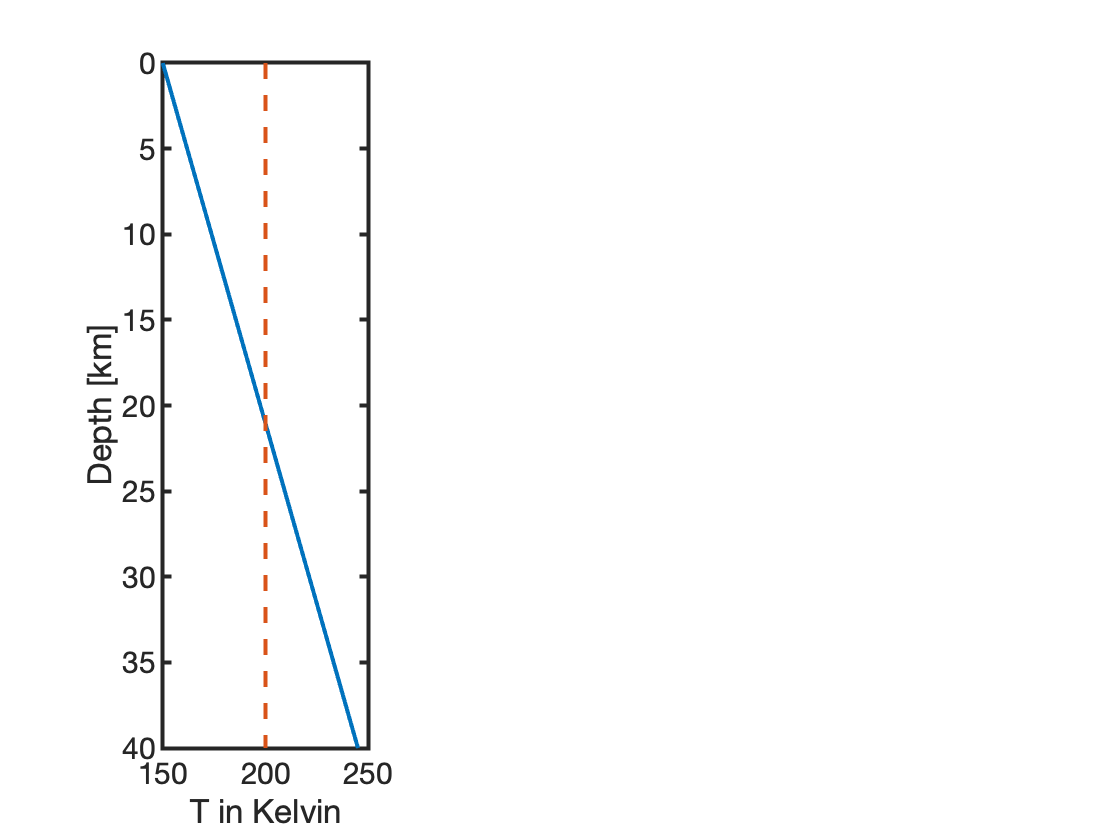

subplot 131
plot(T,depth), hold on
plot(Tmelt*[1 1],[0 H],'--')
set(gca','ydir','reverse')
ylabel('Depth [km]'), xlabel('T in Kelvin')
pbaspect([.3 1 1])

You can select the appropriate part of the T vector as follows

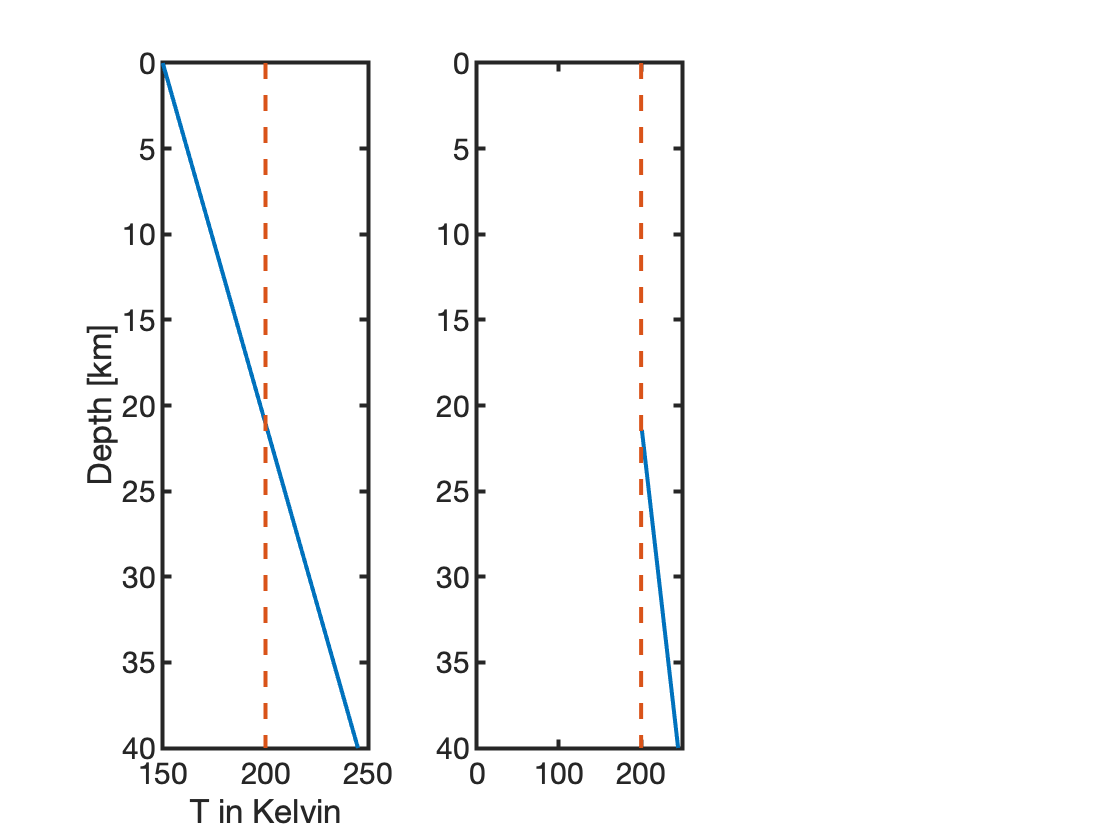

Tpartial = T(T>Tmelt);
depth_partial = depth(T>Tmelt);
figure(h)
subplot 132
plot(Tpartial,depth_partial), hold on
plot(Tmelt*[1 1],[0 H],'--')
set(gca','ydir','reverse')
xlim([0 250])
pbaspect([.3 1 1])

You can also generate an index vector, i.e., zeros and ones, that tells you where partial melt is

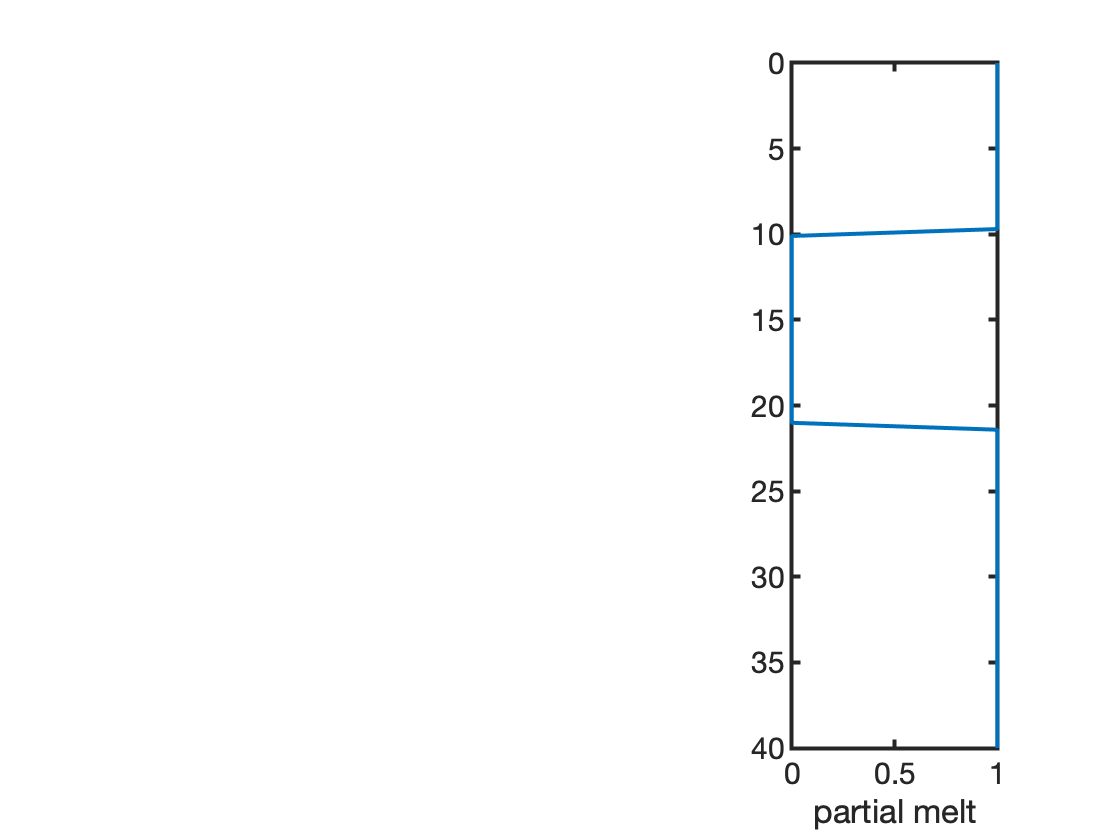

clf
ind_partial = T>Tmelt | depth <10;
figure(h)
subplot 133
plot(ind_partial,depth), hold on
set(gca','ydir','reverse')
xlabel('partial melt')
pbaspect([.3 1 1])

## Anonymous functions

An [anonymous function](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html) is one that is not stored in a program file. The most obvious reason this might be useful is that is allows you to define small functions on the fly, without having to write and separate function file.

For example, the thermal conductivity of ice is the following function of temperature $\kappa(T) = 0.4685 + \frac{488.12}{T} $. Our code will use this many times, so to avoid copy-and-paste errors and to ensure consistency, this should be defined as a reusable user defined function.

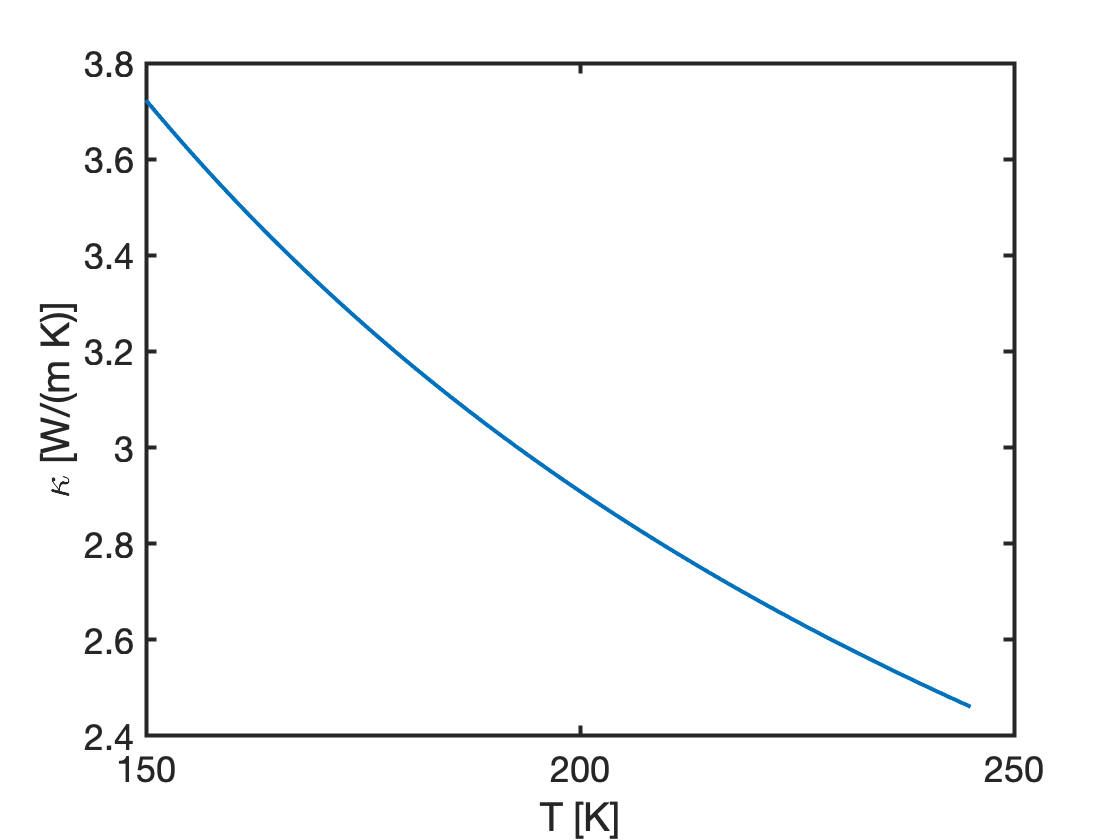

T = linspace(Tsurf,Tbase,1e2);
% kappa = kappa_ice(T); % use proper function
figure
plot(T,kappa_ice(T)), hold on
xlabel('T [K]'), ylabel('\kappa [W/(m K)]')

Alternatively we could simply defince the following anonymous function

T

T =   150.0000  150.9596  151.9192  152.8788  153.8384  154.7980  155.7576  156.7172  157.6768  158.6364  159.5960  160.5556  161.5152  162.4747  163.4343  164.3939  165.3535  166.3131  167.2727  168.2323  169.1919  170.1515  171.1111  172.0707  173.0303  173.9899  174.9495  175.9091  176.8687  177.8283  178.7879  179.7475  180.7071  181.6667  182.6263  183.5859  184.5455  185.5051  186.4646  187.4242  188.3838  189.3434  190.3030  191.2626  192.2222  193.1818  194.1414  195.1010  196.0606  197.0202


kappa_ice2 = @(T) 0.4685 + 488.12./T 

kappa_ice2 = function_handle with value:
    @(T)0.4685+488.12./T


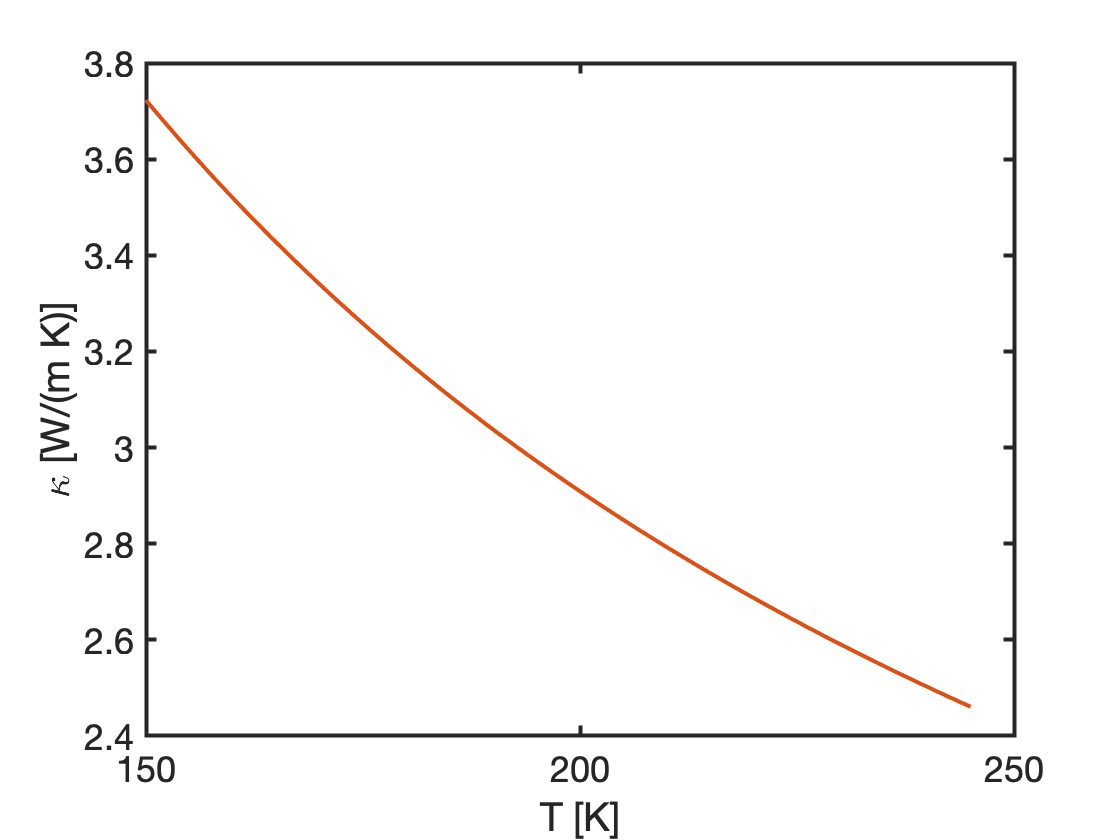

plot(T,kappa_ice2(T),'-')
xlabel('T [K]'), ylabel('\kappa [W/(m K)]')

Anaonymous function can be as complicated as you like. They can have multiple variables. You can have anonymous function of anonymous functions. 

## Auxillary functions

function [kappa] = kappa_ice(T)
    % author: Marc Hesse
    % date: 30 Jan 2018
    % Description: Evaluates temperature dependent conductivity of ice, 
    % based on Castillo-Rogex et al (2007), Icarus, 190(1), 179-202
    % Input: T = array containing temperatures in Kelvin
    % Output: kappa = thermal conductivity of ice in W/(m K)
    kappa = 0.4685 + 488.12./T;
end